# Gabriel Cardoso RA: 18.00477-6

clear all

numerador = [5];
denominador = [1,2,0];
Gm = tf(numerador,denominador)


Gm =
 
      5
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.



% Pelo Sisotool deu para encontrar:
Gmf = feedback(Gm,1)


Gmf =
 
        5
  -------------
  s^2 + 2 s + 5
 
Continuous-time transfer function.



stepinfo(Gmf)

ans = struct with fields:
        RiseTime: 0.6903
    SettlingTime: 3.7352
     SettlingMin: 0.9149
     SettlingMax: 1.2079
       Overshoot: 20.7866
      Undershoot: 0
            Peak: 1.2079
        PeakTime: 1.5658


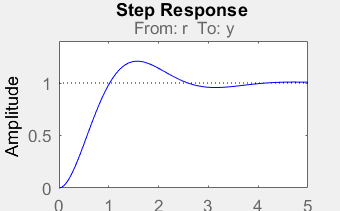

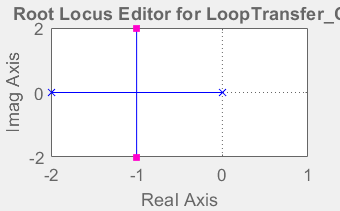

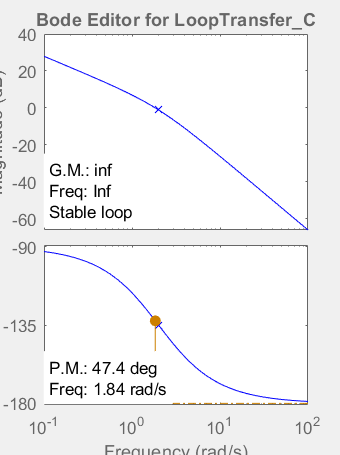


sisotool(Gm)


% p o pico do grafico
p = 1.21

p = 1.2100

T_s = 4

T_s = 4

% 1 foi para t-> infinito
Mp = (p - 1)*100

Mp = 21.0000

## Valor do ganho Mp = 16%

Kp = 0.80665

Kp = 0.8067

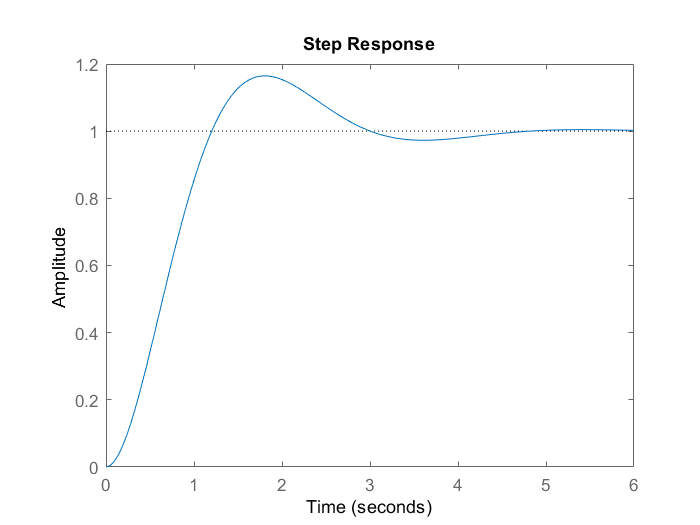

Gmf = feedback(Kp*Gm,1);
step(Gmf)

stepinfo(Gmf)

ans = struct with fields:
        RiseTime: 0.8141
    SettlingTime: 4.0307
     SettlingMin: 0.9021
     SettlingMax: 1.1646
       Overshoot: 16.4647
      Undershoot: 0
            Peak: 1.1646
        PeakTime: 1.7960


## Para Ts = 2 e Mp = 16

num = [1,2.128]

num =     1.0000    2.1280


den = [1,9.638]

den =     1.0000    9.6380


Gc = 3.6226*tf(num,den)


Gc =
 
  3.623 s + 7.709
  ---------------
     s + 9.638
 
Continuous-time transfer function.



Gmf2 = feedback(Gc*Gm,1)


Gmf2 =
 
           18.11 s + 38.54
  ---------------------------------
  s^3 + 11.64 s^2 + 37.39 s + 38.54
 
Continuous-time transfer function.



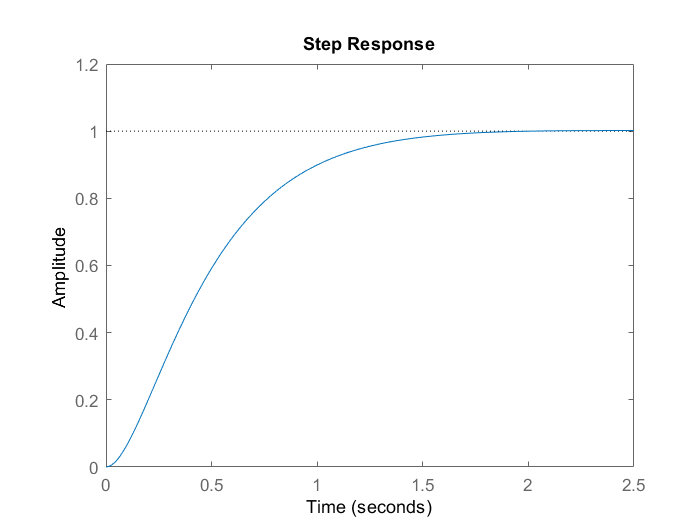

step(Gmf2)